clc; clear all; close all;
setenv('ROS_MASTER_URI','http://192.168.245.132:11311');
setenv('ROS_IP','192.168.245.1');
rosshutdown;
rosinit('192.168.245.132', 11311);

The value of the ROS_IP environment variable, 192.168.245.1, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_04635 with NodeURI http://192.168.245.1:56600/ and MasterURI http://192.168.245.132:11311.



%Inicializa trajAct e gripAct
[trajAct,trajGoal] = rosactionclient('/pos_joint_traj_controller/follow_joint_trajectory','control_msgs/FollowJointTrajectory','DataFormat','struct');
trajAct.FeedbackFcn = []; 
trajAct.ResultFcn = []; 
[gripAct, gripGoal] = rosactionclient('/gripper_controller/follow_joint_trajectory', 'control_msgs/FollowJointTrajectory', 'DataFormat', 'struct');
gripAct.FeedbackFcn = [];
gripAct.ResultFcn = [];
waitForServer(gripAct);

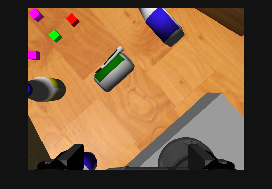

rgbSub   = rossubscriber('/camera/rgb/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
rgbMsg   = receive(rgbSub,3);
rgbImg   = rosReadImage(rgbMsg);
imshow(rgbImg);

addpath('C:\Users\roboime\Downloads\');

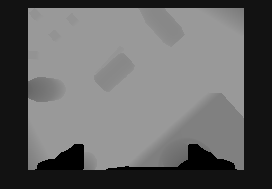

% load('C:\Users\roboime\Downloads\Color_Detector.mat','colorDetector'); 
imTest = rgbImg; 
% [dbox,dscore,dlabel] = detect(colorDetector,imTest);
% labelsWithScores = string(dlabel) + ": " + string(dscore);
% imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
% imshow(imTested);
 pause(2); 
depthSub = rossubscriber('/camera/depth/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
depthMsg = receive(depthSub,3);
depthImg = rosReadImage(depthMsg);
imshow(depthImg);




% addpath('C:\Users\roboime\Downloads\');
% load('C:\Users\roboime\Downloads\Depth_Detector.mat','shapeDetector');
% depthImgNorm = mat2gray(depthImg);  % Normaliza para [0, 1]
% depthImgRGB = uint8(depthImgNorm * 255);  % Converte para imagem tipo uint8
% imTest = repmat(depthImgRGB, 1, 1, 3);  % Converte para 3 canais RGB
% [dbox,dscore,dlabel] = detect(shapeDetector,imTest);
% labelsWithScores = string(dlabel) + ": " + string(dscore);
% imTested = insertObjectAnnotation(imTest, "rectangle", dbox, labelsWithScores);
% imshow(imTested);
% pause(5);

jointSub = rossubscriber("/joint_states",'DataFormat','struct')

jointSub =   Subscriber with properties:

                      TopicName: '/joint_states'
                  LatestMessage: []
                    MessageType: 'sensor_msgs/JointState'
                     BufferSize: 1
    MessagePreprocessingEnabled: 0
                  NewMessageFcn: []
                     DataFormat: 'struct'


waitForServer(trajAct);
modelSub = rossubscriber('/gazebo/model_states', 'gazebo_msgs/ModelStates');
UR5e = loadrobot("universalUR5e", DataFormat = "struct");
tform = UR5e.Bodies{3}.Joint.JointToParentTransform;
UR5e.Bodies{3}.Joint.setFixedTransform(tform*eul2tform([pi/2,0,0]));  
tform = UR5e.Bodies{4}.Joint.JointToParentTransform;
UR5e.Bodies{4}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));
tform = UR5e.Bodies{7}.Joint.JointToParentTransform;
UR5e.Bodies{7}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));    
% Cria resolvedor de cinemática inversa
ik = inverseKinematics("RigidBodyTree", UR5e);
rng(1);
obstacles = Obstaculos(modelSub); %obstaculos file
rrt = manipulatorRRT(UR5e, obstacles, ValidationDistance = 0.1, IgnoreSelfCollision=true );
abrir_garra(0, gripGoal, gripAct);%abrir garra 
goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [-0.36 -0.01 0.45], [0.1 0.1 0 -.1 0 0]); %cinematica inversa

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = 0

config =     1.9696   -0.3790    1.2194   -1.5905    0.0000   -0.3514


plannedpath = plan(rrt, [0 0 0 0 0 0], goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal(rrtpath(i,:), trajGoal); %packTrajGoal
    sendGoal(trajAct,trajGoal); 
end
goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [-0.362 -0.01 0.23], [0.1 0.1 0 -.1 0 0]);

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = 0

config =     2.4203   -0.1474    1.2215   -2.2729   -0.0000   -0.3493



plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
    sendGoal(trajAct,trajGoal); 
end
pause(2);
abrir_garra(0.205, gripGoal, gripAct); %abrir_garra e packGripGoal
pause(6);
goalconfig_trocado = ajuste(goalconfig_trocado, 2, -.7, 2, jointSub, trajGoal, trajAct);%ajuste
goalconfig_trocado = ajuste(goalconfig_trocado, 3, .45, 2, jointSub, trajGoal, trajAct);
pause(3);
abrir_garra(0,gripGoal,gripAct);
pause(3);
disp('Último ponto planejado:')

Último ponto planejado:


disp(rrtpath(end,:))

    2.4203   -0.1474    1.2215   -2.2729   -0.0000   -0.3493




goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [.460 -.07 0.247], [0 .5 -.5 0 0 0]);

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = -0.5000

config =    -1.5798   -0.4959    1.7103    2.0757   -0.0000    0.1395


plannedpath = plan(rrt, [0 0 0 0 0 0] , goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
    sendGoal(trajAct,trajGoal); 
end
abrir_garra(0.5153, gripGoal, gripAct);
pause(5);
goalconfig_trocado = ajuste(goalconfig_trocado, 2, .7, 2, jointSub, trajGoal, trajAct)

goalconfig_trocado =    -1.5798    0.2041    1.7103    2.0757   -0.0000    0.1395


goalconfig_trocado = ajuste(goalconfig_trocado, 3, -2.3199 - goalconfig_trocado(3)+3.3, 4, jointSub, trajGoal, trajAct)

goalconfig_trocado =    -1.5798    0.2041    0.9801    2.0757   -0.0000    0.1395


pause(3);
abrir_garra(0,gripGoal,gripAct);
pause(5);
goalconfig_trocado = rotelem([0 0 0 0 0 0], [1 1 1 1 1 1], [1 2 3 4 5 6], jointSub, trajGoal, trajAct); %rotelem
goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [0.655 0.016 0.32], [0 .5 -.5 0 0 0])

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = -0.5000

config =    -0.5680   -0.9646    1.8001    1.5326   -0.0000    0.2293


goalconfig_trocado =    -0.5680   -0.9646    1.8001    1.5326   -0.0000    0.2293


plannedpath = plan(rrt, [0 0 0 0 0 0] , goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
    sendGoal(trajAct,trajGoal); 
end


goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [0.655 0.016 0.245], [0 .5 -.5 0 0 0]);

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = -0.5000

config =    -0.7315   -0.9795    1.8001    1.7110   -0.0000    0.2293


pause(3);
plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
    sendGoal(trajAct,trajGoal); 
end
abrir_garra(0.2222, gripGoal, gripAct);
pause(6);
goalconfig_trocado = ajuste(goalconfig_trocado, 2, .7, 2, jointSub, trajGoal, trajAct)

goalconfig_trocado =    -0.7315   -0.2795    1.8001    1.7110   -0.0000    0.2293


lixo(1, trajGoal, trajAct, gripGoal, gripAct); %lixo e mover_para
pause(3);

goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [-.5 .265 .3], [1 -1 0 0 0 0]);

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = 0

config =     1.7992    0.2370    0.8456   -2.0362    0.0000   -0.7252


plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
    sendGoal(trajAct,trajGoal); 
end
pause(2);
goalconfig_trocado = cinematicainversa([-pi/2 -pi 0], UR5e, ik, [-.5 .265 .13], [1 -1 0 0 0 0])

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = 0

config =     1.9623    0.5016    0.8456   -2.4639   -0.0000   -0.7252


goalconfig_trocado =     1.9623    0.5016    0.8456   -2.4639   -0.0000   -0.7252


plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
    sendGoal(trajAct,trajGoal); 
end

abrir_garra(0.226, gripGoal, gripAct);
pause(6);
goalconfig_trocado = ajuste(goalconfig_trocado, 2, -.7, 2, jointSub, trajGoal, trajAct);
lixo(1, trajGoal, trajAct, gripGoal, gripAct);
pause(3);

goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [-.625 .28 .3], rrtpath(end,:));

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = 0.8456

config =     1.4232    0.5009    0.9537   -1.9241   -0.0000    0.9537


plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal(rrtpath(i,:), trajGoal);
    sendGoal(trajAct,trajGoal); 
end
pause(2);

goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [-.623 .3 .085], rrtpath(end,:));

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = 0.9537

config =     1.5676    0.7888    0.9280   -2.3564   -0.0000    0.9280


pause(3);
plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal([rrtpath(i,:)], trajGoal);
    sendGoal(trajAct,trajGoal); 
end

abrir_garra(.22, gripGoal, gripAct);
pause(5);
goalconfig_trocado = ajuste(goalconfig_trocado, 2, -.7, 2, jointSub, trajGoal, trajAct)

goalconfig_trocado =     1.5676    0.0888    0.9280   -2.3564   -0.0000    0.9280


lixo(2,trajGoal, trajAct,gripGoal, gripAct);
pause(3);

goalconfig_trocado = rotelem([0 0 0 0 0 0], [1 1 1 1 1 1], [1 2 3 4 5 6], jointSub, trajGoal, trajAct);

goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [-.525 -.09 .3], [-.1 .1 0 0 0 0]);

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = 0

config =    -1.2646   -0.6002   -1.1481    1.8647    0.0000   -1.1481


pause(3);
plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal([rrtpath(i,:)], trajGoal);
    sendGoal(trajAct,trajGoal); 
end

goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [-.525 -.06 .09], [-.1 .1 0 0 0 0]);

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = 0

config =    -1.4516   -0.8363   -1.2020    2.2879   -0.0000   -1.2020


pause(3);
plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal([rrtpath(i,:)], trajGoal);
    sendGoal(trajAct,trajGoal); 
end

abrir_garra(.212, gripGoal, gripAct);
pause(5);
goalconfig_trocado = ajuste(goalconfig_trocado, 2, .7, 2, jointSub, trajGoal, trajAct)

goalconfig_trocado =    -1.4516   -0.1363   -1.2020    2.2879   -0.0000   -1.2020


lixo(2,trajGoal, trajAct,gripGoal, gripAct);
pause(3);

abrir_garra(1, gripGoal, gripAct);
pause(5);
abrir_garra(0, gripGoal, gripAct);
pause(2);

goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [.687 -.085 .4], [-.1 .1 0 0 0 0]);

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = 0

config =    -1.2183   -0.4629    1.6415   -1.4605   -3.1416   -1.5001


pause(3);
plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal([rrtpath(i,:)], trajGoal);
    sendGoal(trajAct,trajGoal); 
end
goalconfig_trocado = cinematicainversa([-pi -pi 0], UR5e, ik, [.687 -.085 .14], [-.1 .1 0 0 0 0]);

ans = struct with fields:
        JointName: 'elbow_joint'
    JointPosition: 0


JointPosition = 0

config =    -0.5829   -1.1927    1.6415    1.7757    0.0000    1.6415


pause(3);
plannedpath = plan(rrt, rrtpath(end,:), goalconfig_trocado);
shortenedPath = shorten(rrt,plannedpath,40);
rrtpath = interpolate(rrt,shortenedPath,10);
for i = 1:size(rrtpath, 1)
    trajGoal = packTrajGoal([rrtpath(i,:)], trajGoal);
    sendGoal(trajAct,trajGoal); 
end

abrir_garra(0.62, gripGoal, gripAct);
pause(5);


goalconfig_trocado = ajuste(goalconfig_trocado, 2, .7, 2, jointSub, trajGoal, trajAct)

goalconfig_trocado =    -0.5829   -0.4927    1.6415    1.7757    0.0000    1.6415


lixo(1,trajGoal, trajAct,gripGoal, gripAct);
pause(3);